% เคลียร์ข้อมูลก่อนรันโค้ดใหม่
clear all, close all, clc

% เพิ่มเส้นทางของโฟลเดอร์ '0.Surrogate model & Optimization'
% และโฟลเดอร์ย่อยทั้งหมดที่อยู่ภายในโฟลเดอร์นี้
folder_path = '0.Surrogate model & Optimization';
addpath(genpath(folder_path));

% โหลดข้อมูลจาก .m file
load('')


% เลือกโมเดลที่ต้องการ ในที่นี้ใช้ KRIGexp2 จาก data_for_opt_KRIGexp2.mat
% KRIGexp2 เป็นโมเดลที่มีความแม่นยำสูงสุดจากโมเดลทั้งหมดที่ศึกษา
% สามารถใช้โมเดลอื่นได้จากไฟล์
% results_data_KRIG_model.mat
% results_data_MARS_model.mat
% results_data_RBF01_model.mat

% % % run algorithms
algo = {'NSGA_II'}; %
for m = 1:1, % จำนวนอัลกอริทึม
    algo_sel = [m];% req
    nrun = 5;% req please change to 5
    nvar = [24];% no. of design variables of the test problems (จำนวนตัวแปร X)

% กำหนดขอบบนขอบล่างของตัวแปรต้น
%     X =  [X1, X2, X3, X4, X5, X6, X7, X8, X9, X10, X11, X12,...
%           X13, X14, X15, X16, X17, X18, X19, X20, X21, X22, X23, X24]
    lb = [11.55, 30.40, 0, 4.87, 8.64, 3.50, 38.87, 0, 2.65, -4.33, 3.31, 0,...
        11.60, 59.75, 0, 2.29, -7.01, 9.41, 26.19, 3.50, 38.23, 0, 36.39, 23.09 ]; 
    ub = [14.25, 56.78, 200, 7.53, 19.60, 14.28, 75.59, 100, 3.57, 1.51, 12.01, 33.66,...
        14.41, 82.52, 200, 2.56, -4.94, 12.74, 35.57, 14.38, 77.79, 100, 97.29, 31.33];
%     lb = min(clean_data(:,1:24));
%     ub = max(clean_data(:,1:24));
    nbit = 1000; % 
    nloop = 100;% req จำนวนรอบ
    nsol = 100;% req จำนวนประชากร
    narchive = nsol;
% กำหนดขอบบนขอบล่างของตัวแปรต้น    
    a = lb;
    b = ub;
%     กำหนด Objective function (จากไฟล์ objective_COP.m)
    fun = @(x) objective_HeatPower(x, X_train, results);
    for i=algo_sel  %%%% algorithm
        filename=[char(algo(i,:)) '.mat'];
        for j=1:nrun     %%%%   optimization run
            RR=[i j];
            tic
            rst(j)=feval(char(algo(i,:)),fun,filename,nloop,nsol,nvar,nbit,narchive,a,b);
            toc
        end
        %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%         Output rst
        save(filename,'rst');
        % ตั้งชื่อไฟล์และเส้นทางไฟล์
%         output_filename = [char(algo(algo_sel)) '_best_table.xlsx'];
%         % บันทึกตารางลงในไฟล์ Excel
%         writetable(best_table, output_filename);
    end
end
% % % นำข้อมูลจากการ Optimization ไปวิเคราะห์กับข้อมูลจริงและสรุปผล

for i = 1:nrun;
    Y1_best = rst(i).fpareto{1,100}(1,:);
    Y2_best = -(rst(i).fpareto{1,100}(2,:));

    subplot(3, 2, i);
    scatter(Y1_best, Y2_best, 10, 'filled');
    xlabel("Electric Power");
    ylabel("Heat Rejection")
    title("Pareto front",{i});
%      legend('Raw', 'Cleaned');

end

X_best = rst(5).ppareto{1,100};
Y1_best = rst(5).fpareto{1,100}(1,:);
Y2_best = -(rst(5).fpareto{1,100}(2,:));
YY_HeatRejectionRatio_best = Y2_best./Y1_best;

scatter(Y1_best, Y2_best, 30,"blue");
xlabel("Electric Power (kW)");
ylabel("Heat Rejection (kW)");
title("Pareto front");


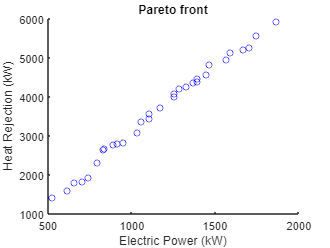

% scatter(Y1_best, Y2_best, 30,"blue");
% xlabel("Electric Power (kW)");
% ylabel("Heat Rejection (kW)");
% title("Pareto front");


% % % % % % % % % สร้างตารางข้อมูล % % % % % % % %
% best_array = [X_best' Y1_best' Y2_best'];
% best_table = array2table(best_array);
% % กำหนดชื่อคอลัมน์
% best_table.Properties.VariableNames = column_names;
% 
% % % บันทึกตารางเป็นไฟล์ Excel
% writetable(best_table, 'best_tablen100.xlsx');

% scatter(Y1_best, Y2_best, 10, 'filled', 'MarkerFaceColor', 'orange');
% xlabel("Electric Power");
% ylabel("Heat Rejection");
% title("Pareto front");
